# ECE 133A Homework 1

## Exercise A1.10

initialize variables

load('mnist_train.mat');
digits = digits(:, 1:10000);
[n, N] = size(digits);
K = 20;
class = randi(K, 1, N);
Z = zeros(n, K);
D = zeros(K, N);
Jprev = NaN;

for iter = 1:100
    for i = 1:K
        I = find(class == i);

        % update columns of Z
        curr = zeros(n, 1);
        for idx = I
            curr = curr + digits(:,idx);
        end

        curr = curr / length(I);
        Z(:,i) = curr;
        %%%%%%%%%%%%%%%%%%%%%
    end

    for i = 1:K
        for j = 1:N
            D(i, j) = norm(Z(:,i) - digits(:,j));
        end
    end

    for j = 1:length(D)
        [m, i] = min(D(:,j));
        class(j) = i;
    end

    J = (1 / N) * norm(D)^2;
    if iter > 1
        if abs(J - Jprev) < 1e-5 * J
            break;
        end

        Jprev = J;
    end
end



Display figure

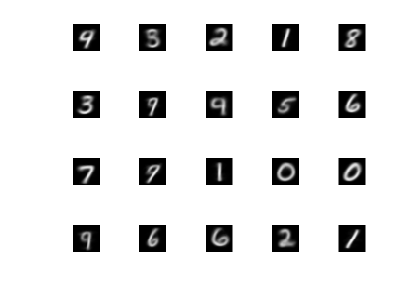

for k=1:20
    subplot(4,5,k)
    imshow(reshape(Z(:,k),28,28));
end